# Preparation

clear;
clc;
cd 'C:\Users\james\Desktop\Spring 2023\Econ 4360'; 
% Read in and separate numerical data from dates (first column) and header
T = readtable('ExcerciseSet1_YuanzhanGao_AdityaKumar.xlsx','sheet','Returns');

AssetReturn_dollar = T(1:361, 9:14);
AssetReturn_dollar = AssetReturn_dollar{:,:};
AssetReturn_percent = T(2:361, 2:7);
AssetReturn_percent = AssetReturn_percent{:, :};

## Graph the cumulative returns to a $1 investment in all three assets in MATLAB. State both the cumulative dollar returns and their annualized mean returns in a table below the graph.

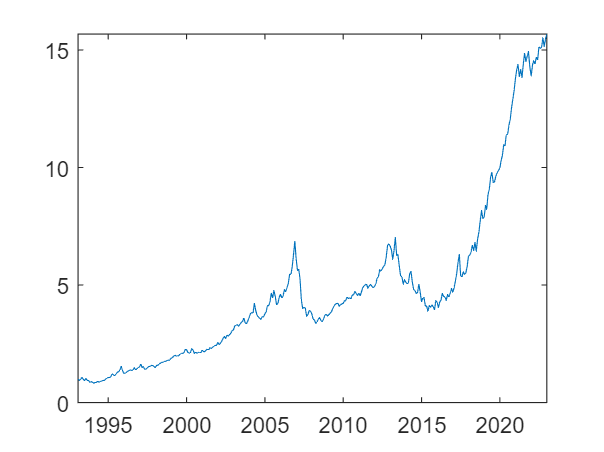

date = datetime(T.Date(1:361));
figure
AssetReturn_dollar_flip = flip(AssetReturn_dollar);
plot(date, AssetReturn_dollar_flip(:, 1))